## Simulazione Filtri

#### creazione variabili

syms R1 R2 C1 C2 omega

### CRRC

Metto che inizialmente il segnale ha valore unitario

Dopo il primo attenuatore, il segnale ha una tensione Vth con un impedenza di uscita Rth:

[Vth, Rth] = calcola_thevenen(impedenza_condensatore(C1, omega), R1)

$$Vth = \frac{R_{1}}{R_{1}-\frac{\mathrm{i}}{C_{1}\,\omega }}$$

$$Rth = \frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}$$

il ramo a destra ha un'impedenza z2:

Z2 = impedenza_condensatore(C2, omega) + R2

$$Z2 = R_{2}-\frac{\mathrm{i}}{C_{2}\,\omega }$$

Allora su questo ramo ci scorre una corrente I2

I2 = Vth / (Rth + Z2)

$$I2 = \frac{R_{1}}{\left(R_{1}-\frac{\mathrm{i}}{C_{1}\,\omega }\right)\,\left(R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{2}\,\omega }\right)}$$

allora la tensione in uscita è:

Vout = I2 * impedenza_condensatore(C2, omega)

$$Vout = -\frac{R_{1}\,\mathrm{i}}{C_{2}\,\omega \,\left(R_{1}-\frac{\mathrm{i}}{C_{1}\,\omega }\right)\,\left(R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{2}\,\omega }\right)}$$

Il guadagno quindi è:

tmp = Vout;
tmp = subs(tmp, C1, 47E-9);
tmp = subs(tmp, C2, 100E-3);
tmp = subs(tmp, R1, 100E+3);
tmp = subs(tmp, R2, 1E+3);
guadagno_val = abs(tmp)^2;
sfasamento_val = angle(guadagno);

### Plot

Prima troviamo l'espressione con i nostri parametri:

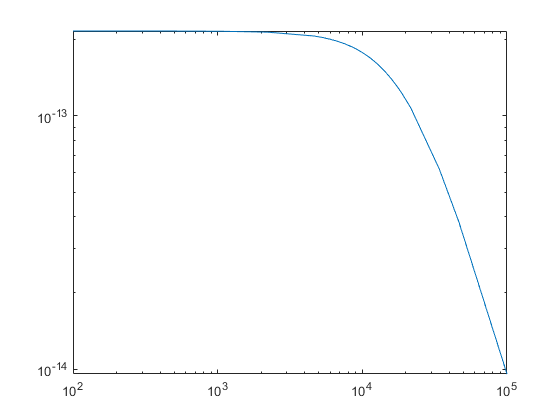


fplot(guadagno_val, [100 100000], "MeshDensity", 10)
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')

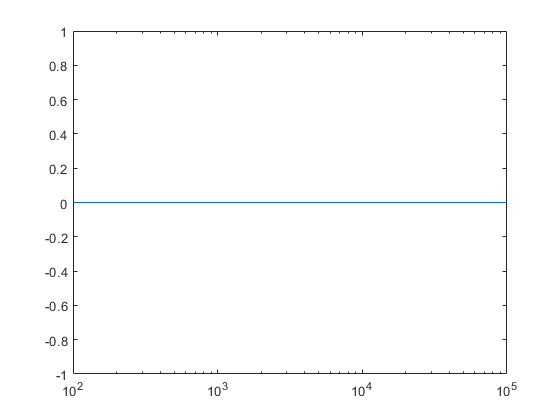

fplot(sfasamento_val, [100 100000], "MeshDensity", 10)
set(gca, 'XScale', 'log')

#### Funzioni thevenen

function [ratio_Vth_Vin,Rth] = calcola_thevenen(r1, r2)
    ratio_Vth_Vin = r2 / (r1 + r2);
    Rth = 1 / (1/r1 + 1/r2);
end
function [Z] = impedenza_condensatore(c, omega)
    Z = 1 / (j  * omega * c);
end